This is a demonstration of how to use the Planet, TestParticle, Point classes for 3D Keplerian orbit simulations. 

Start by making a few points using the different constructors:

p1 = particle.Point % default point at (0,0,0)

p1 =   Point with properties:

     x: 0
     y: 0
     z: 0
     R: 0
    Th: 0
    Ph: 0


p2 = particle.Point(1,2,3)

p2 =   Point with properties:

     x: 1
     y: 2
     z: 3
     R: 3.7417
    Th: 0.64052
    Ph: 1.1071


p3 = particle.Point('rand')

p3 =   Point with properties:

     x: 4.9477
     y: -0.81358
     z: -0.4553
     R: 5.0348
    Th: 1.6614
    Ph: -0.16298


Use dot notation to call properties or methods of the objects:


p2.x

ans =      1



p1.y=2; p1.y

ans =      2



p3.move(1,2,-2); p3

p3 =   Point with properties:

     x: 5.9477
     y: 1.1864
     z: -2.4553
     R: 6.5431
    Th: 1.9555
    Ph: 0.19689


Calculate distances between points:

d12 = p1.dist(p2);
d23 = p2.dist(p3);
d31 = p3.dist(p1);

disp(['1->2: ' num2str(d12) ' | 2->3: ' num2str(d23) ' | 3->1: ' num2str(d31)]);

1->2: 3.1623 | 2->3: 7.4096 | 3->1: 6.4858


Calculate the angle between two points (in degrees)

ang = rad2deg(p1.phiTo(p3))

ang =        172.21


Put the points in a vector of points and plot them

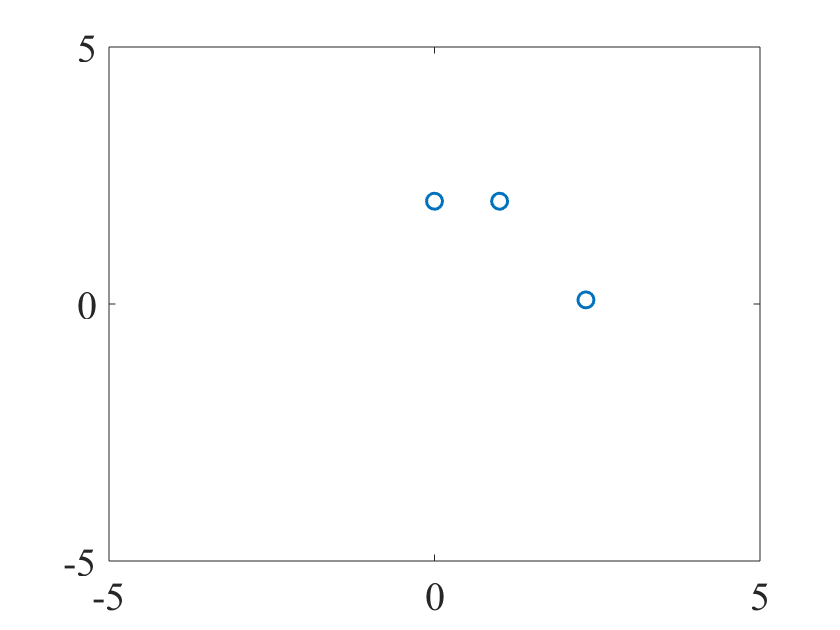


p4 = particle.Point('rand');

p = [p1 p2 p3 p4];

p.plot2D; 

Generate some test particles  

dp1 = particle.TestParticle

dp1 =   TestParticle with properties:

    v_x: 0
    v_y: 0
    v_z: 0
      x: 0
      y: 0
      z: 0
      R: 0
     Th: 0
     Ph: 0



dp2 = particle.TestParticle('rand','rand')

dp2 =   TestParticle with properties:

    v_x: -0.036587
    v_y: -0.0095135
    v_z: 0.056188
      x: -1.6042
      y: -3.8392
      z: -4.1569
      R: 5.8815
     Th: 2.3557
     Ph: -1.9666


Use a static function to make a bunch of random particles:

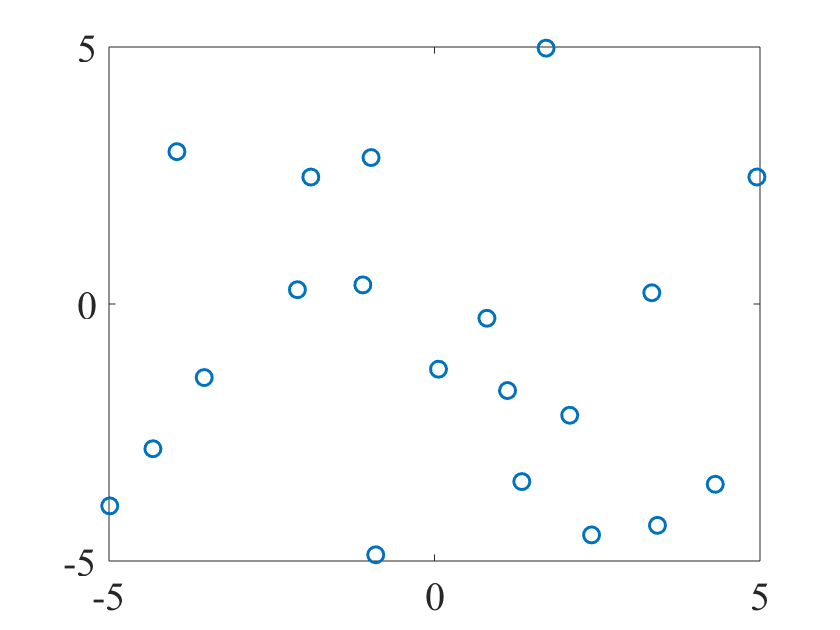

dp = particle.TestParticle.makeRandomParticles(20); % notice this is a static function that doesn't need any particle to be called on. 

dp.plot2D; % calls the Point class plotting tools. 

Move all particles a short distance:

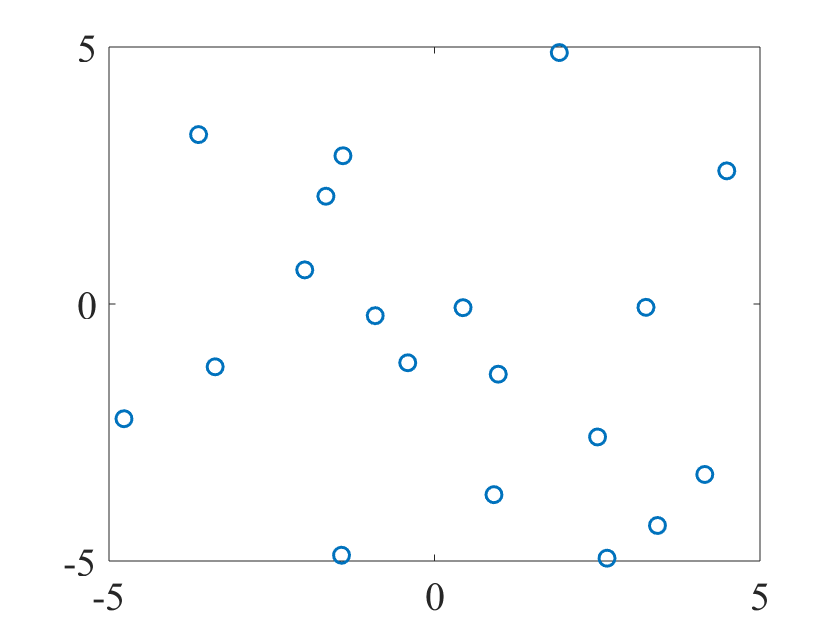


dp.moveAll(3);
dp.plot2D;

Run a simple simulation with constant velocities:

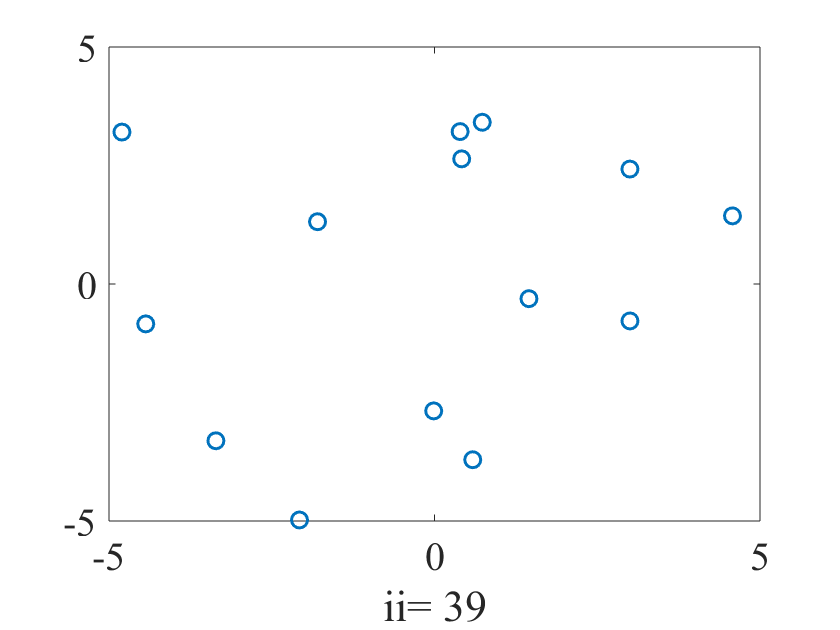


dp = particle.TestParticle.makeRandomParticles(20); % notice this is a static function that doesn't need any particle to be called on. 

for ii=1:100
    
    dp.moveAll(1);
    dp.plot2D;
    xlabel(['ii= ' num2str(ii)]);
    drawnow;
    
end

Put a planet with gravity in the middle, then run the simulation using the object's methods:

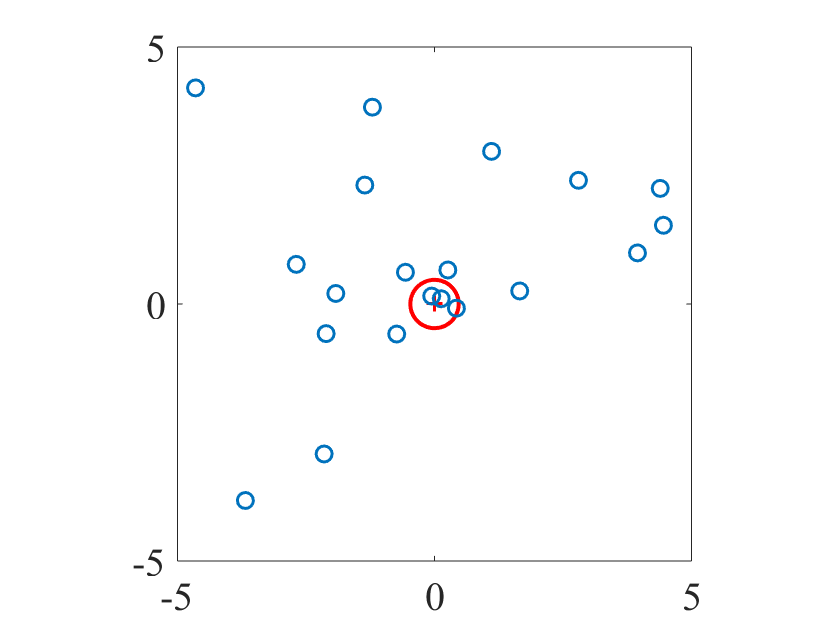

P = particle.Planet; % supports only default constructor

P.makeParticles;

P.run;